# Lab 1 - Edge Detectors

## Setup

### Step 1

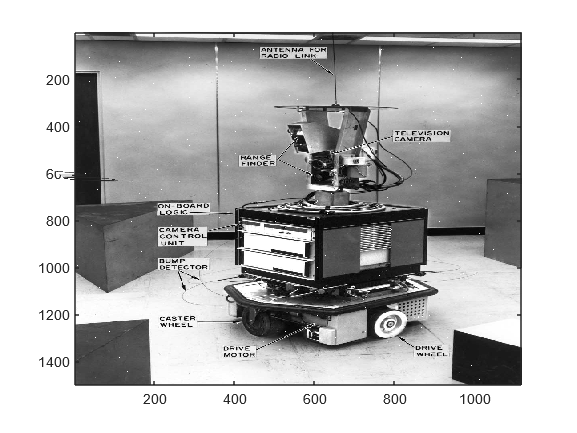

% Clear the variables
clear

% Read and show the provided "shakey" image
shakey = read_image('', 'shakey.150.gif');
show_image(shakey)

% Load variables
load sobel
load roberts
who


Your variables are:

robertsA  robertsB  shakey    sobelX    sobelY    



### Step 2

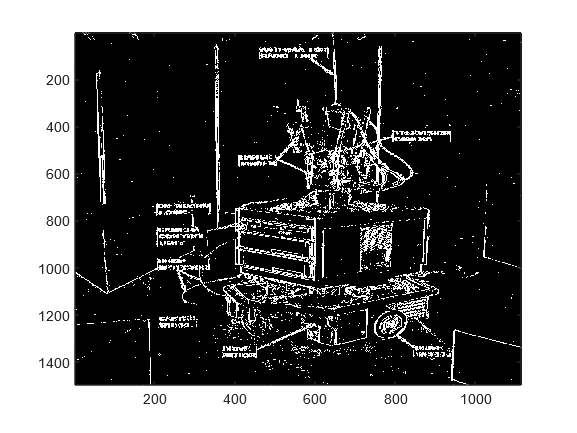

% Convolve the image with horizontal kernel and show it
shakey_sobelX = conv2(shakey, sobelX, 'valid');
show_image(abs(shakey_sobelX) > 60)

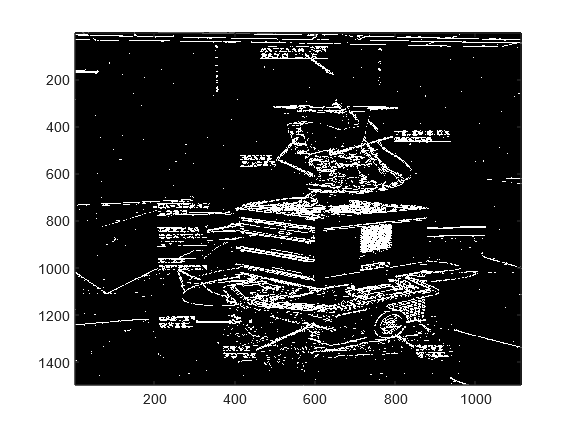

% Convolve the image with vertical kernel and show it
shakey_sobelY = conv2(shakey, sobelY, 'valid');
show_image(abs(shakey_sobelY) > 60)

### Step 3

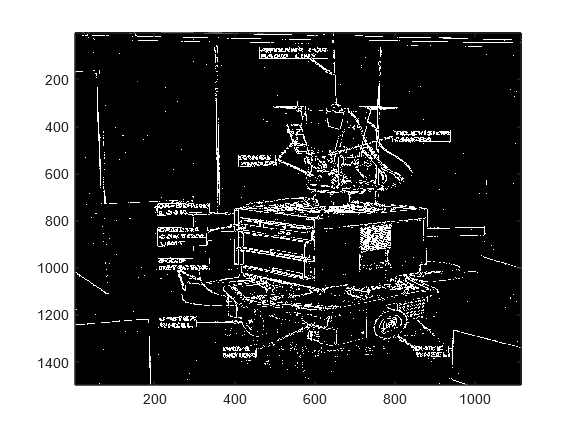

% Convolve the image with horizontal kernel and show it
shakey_robertsA = conv2(shakey, robertsA, 'valid');
show_image(abs(shakey_robertsA) > 20)

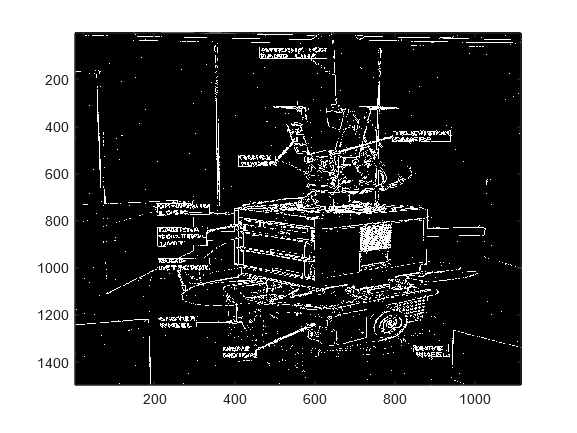

% Convolve the image with vertical kernel and show it
shakey_robertsB = conv2(shakey, robertsB, 'valid');
show_image(abs(shakey_robertsB) > 20)

## Tasks

### Task 1

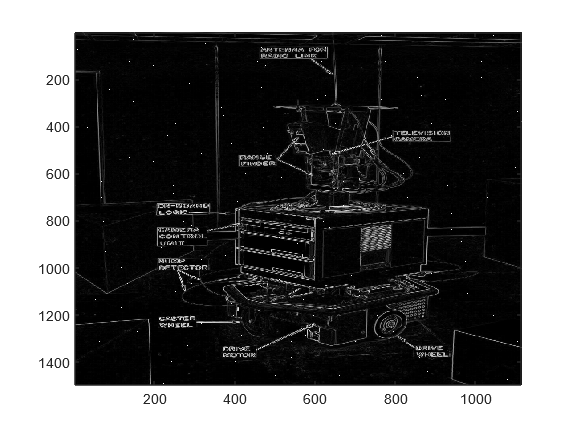

% Compute the magnitude of the 2 gradient matrices and show it
m = magnitude(shakey_sobelX, shakey_sobelY);
show_image(m)

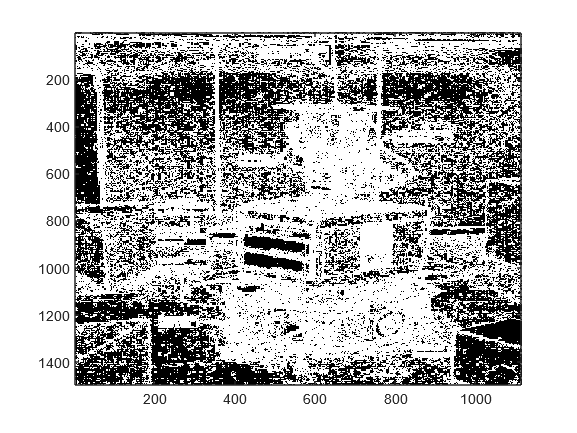


% Plot 4 images with different thresholds
show_image(m > 10)

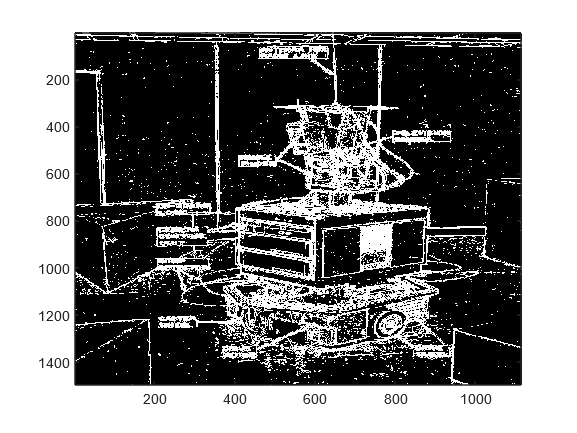

show_image(m > 40)

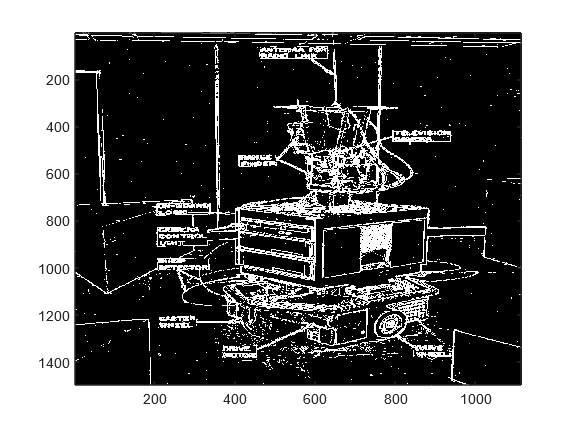

show_image(m > 70)

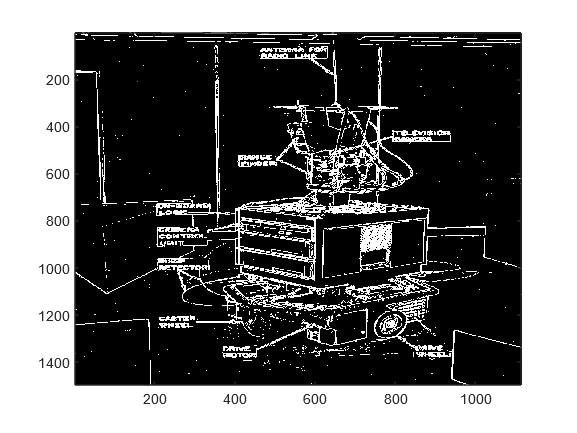

show_image(m > 100)

**QUESTION 1**: What do you notice regarding the effect of changing the threshold?

**ANSWER 1**: The smaller the threshold, the more noise and the more details there are in the image. The bigger the threshold, the less noise and the less details there are. What happens with a low threshold is that we allow even relatively small values to be identified as image edges, and since at least some amount of the rate of change in intensity is present even in plain areas (due to noise), we get lots of pixels identified as edges. In contrast, with high threshold, we care only about the biggest changes in intensity, therefore, only the major contours are identified, leaving out most of the noise and minor edges undetected. In general, we can see a trade-off between image noise and contour smoothness.

### Task 2

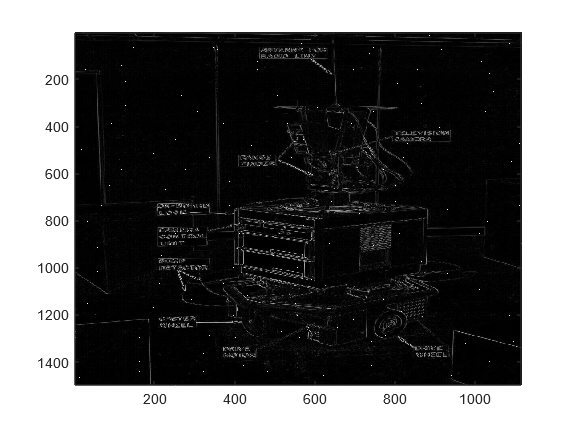

% Compute the magnitude of the 2 gradient matrices and show it
m = magnitude(shakey_robertsA, shakey_robertsA);
show_image(m)

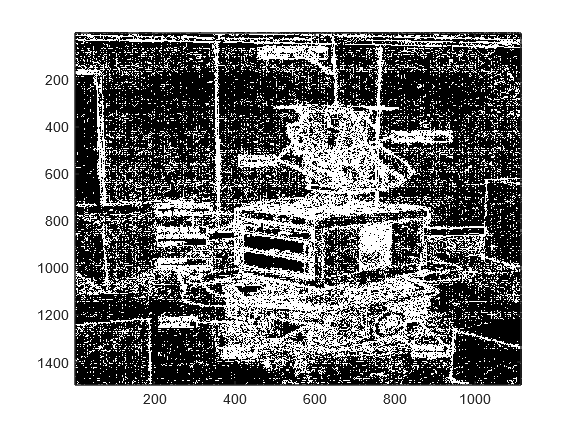


% Plot 4 images with different thresholds
show_image(m > 5)

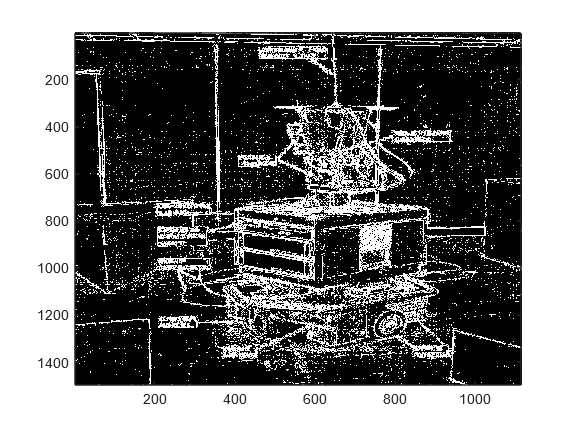

show_image(m > 10)

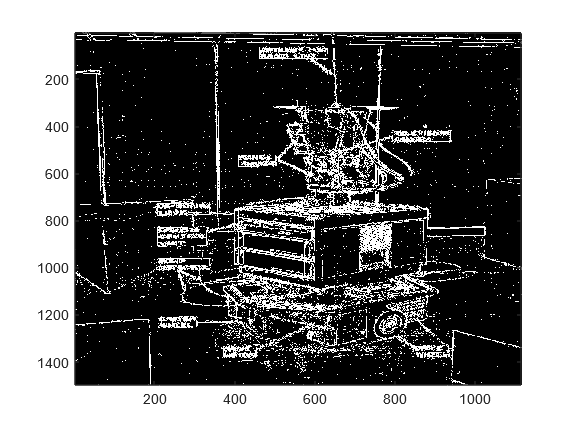

show_image(m > 15)

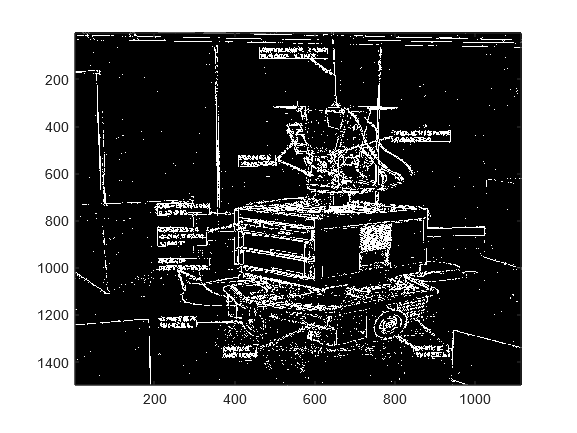

show_image(m > 20)

**QUESTION 2**: What do you notice regarding the difference between Sobel and Roberts?

**ANSWER 2**: Using Roberts filters, the contours are identified with relatively low thresholds, for example, with threshold 20, strong edges are detected and some small ones are even undetected, meaning 20 is slightly too high to capture small details. However, there is more noise too, so the trade-off is more overlapping compared to the trade-off when using Sobel filters. This happens because we compute the gradients at local regions of size 2-by-2 which is more sensitive than when we calculate gradients at 3-by-3 regions because we don't take into account the surrounding pixels which provide more generalized information about the rate of change of intensity in that region and smoothen the gradient.

### Task 3

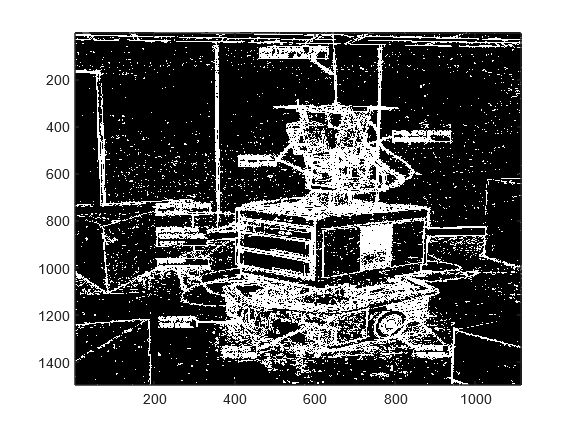

% Compute the approximate magnitude of the 2 gradient matrices and show it
m_a = magnitude_approximation(shakey_sobelX, shakey_sobelY);

% Plot 2 images with different thresholds
show_image(m_a > 40)

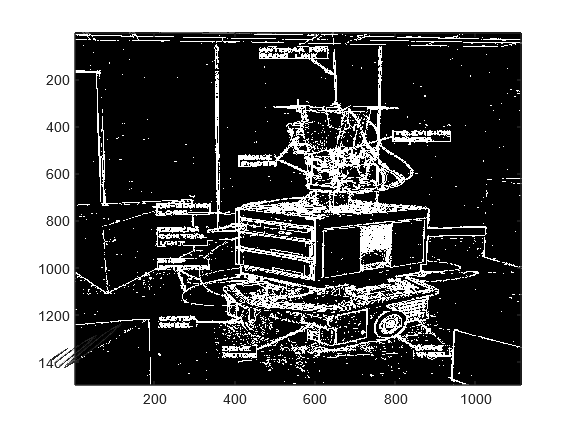

show_image(m_a > 70)

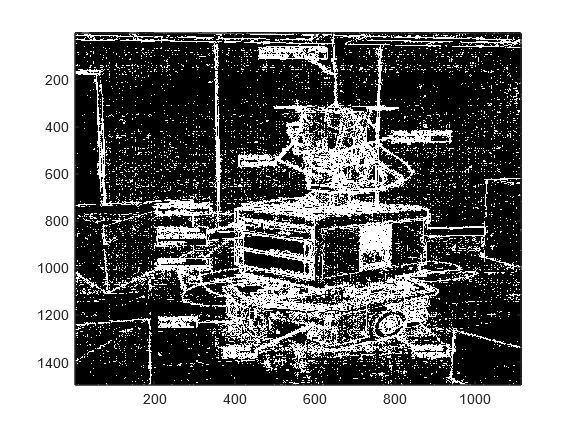

% Compute the approximate magnitude of the 2 gradient matrices and show it
m_a = magnitude_approximation(shakey_robertsA, shakey_robertsB);

% Plot 2 images with different thresholds
show_image(m_a > 10)

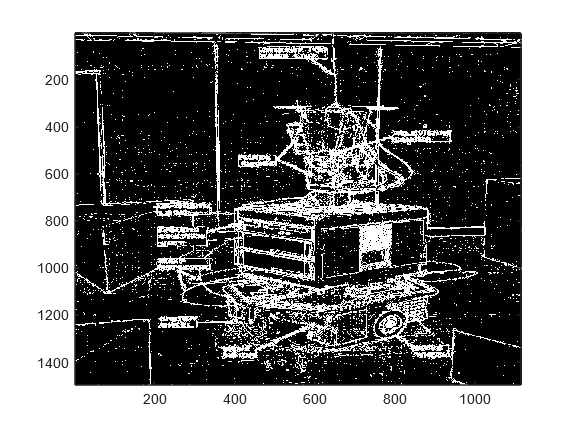

show_image(m_a > 15)

% Check time taken to calculate exact magnitude
t1 = @() magnitude(shakey_sobelX, shakey_sobelY);
t1 = timeit(t1)

t1 = 0.0017


% Check time taken to calculate approximate magnitude
t2 = @() magnitude_approximation(shakey_sobelX, shakey_sobelY);
t2 = timeit(t2)

t2 = 4.9635e-04


% Check the ratio
ratio = t1 / t2

ratio = 3.4285


% Check relative error
[~, rel_err] = calc_error(m_a, m)

rel_err = 0.3148

**QUESTION 3**: What do you notice regarding the difference between magnitude and absolute when calculating the edge?

**ANSWER 3**: When using absolute values we introduce more noise because there is an approximation error (for example, in the case of using Roberts filters the relative error is ~31.48%). However less time is taken to calculate the absolute measure than the exact magnitude (for example, in the case of using Sobel filters, the absolute measure is calculated 3-6 times faster than the magnitude). However, the result is still similar and, if efficiency is required, the absolute measure could be used as a substitute for the exact magnitude measure.